# Introduction: Frequency Domain Methods for Controller Design

The frequency response method of controller design may be less intuitive than other methods you have studied previously. However, it has certain advantages, especially in real-life situations such as modeling transfer functions from physical data. In this tutorial, we will see how we can use the open-loop frequency response of a system to predict its closed-loop time response behavior. 

Key MATLAB commands used in this tutorial are: [`bode`](http://www.mathworks.com/help/ident/ref/bode.html) ,  [`nyquist`](http://www.mathworks.com/help/control/ref/nyquist.html) ,  [`margin`](http://www.mathworks.com/help/toolbox/control/ref/margin.html) ,  [`lsim`](http://www.mathworks.com/help/toolbox/control/ref/lsim.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) , [`feedback`](http://www.mathworks.com/help/toolbox/control/ref/feedback.html) , [`controlSystemDesigner`](http://www.mathworks.com/help/control/ref/controlsystemdesigner-app.html)

## Gain and Phase Margin

Recall from the [Introduction: System Analysis](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemAnalysis) page that the frequency response of a system consists of evaluating how a sinusoidal input to a system is scaled and shifted by the system in steady state. The manner in which the scaling and shifting of the sinusoidal output changes as a function of frequency provides useful information about the system's time response. One aspect, in particular, that a system's frequency response is used for determining is a system's "robustness." For example, how close is the system to becoming unstable? Here we use two quantities, **gain margin** and **phase margin** to indicate the margin the system has before it would go unstable.

Consider the following unity feedback system:

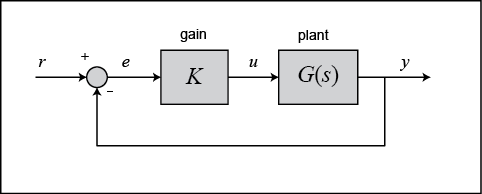

where $K$ is a variable (constant) gain and $G(s)$ is the plant under consideration. The gain margin is defined as the change in open-loop gain required to make the closed-loop system unstable. Systems with greater gain margins can withstand greater changes in system parameters before becoming unstable in closed-loop.

The phase margin is defined as the change in open-loop phase shift required to make the closed-loop system unstable. The phase margin also measures the system's tolerance to time delay. If there is a time delay greater than $PM/\omega_{gc}$ in the loop (where $\omega_{gc}$ is the frequency in rad/sec where the magnitude is 0 dB and PM is the phase margin converted to radians), the closed-loop system will become unstable. The time delay, $\tau_d$, can be thought of as an extra block in the forward path of the block diagram that adds phase lag to the system, but has no effect on the gain. That is, a time delay can be represented as a block with magnitude of 1 and phase $-\omega \tau_d$.

For now, we won't worry about where all this comes from and rather will concentrate on identifying the gain and phase margins on a Bode plot.

The closed-loop system's phase margin is the additional amount of phase lag that is required for the open-loop system's phase to reach -180 degrees at the frequency where the open-loop system's magnitude is 0 dB (the gain crossover frequency, $\omega_{gc}$). Likewise, the gain margin is the additional amount of gain (usually in dB) required for the open-loop system's magnitude to reach 0 dB at the frequency where the open-loop system's phase equals -180 degrees (the phase crossover frequency, $\omega_{pc}$). 

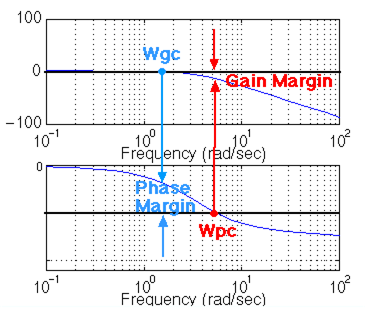

One nice thing about the phase margin is that you don't need to replot the Bode diagram in order to find the new phase margin when changing the loop gain. If you recall, adding gain only shifts the magnitude plot up (or down). This is equivalent to changing the y-axis on the magnitude plot. Finding the phase margin is simply a matter of finding the new gain crossover frequency and reading off the phase margin. Employing the following interactive script, you can alter the additional loop gain and observe the effect on the Bode plot, as well as the resulting gain and phase margins.

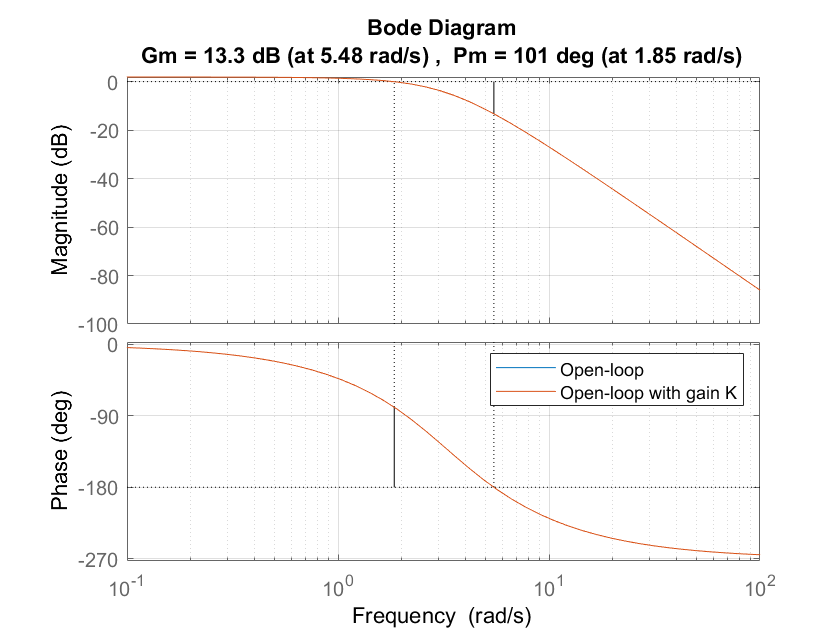

s = tf('s');
G = 50/(s^3 + 9*s^2 + 30*s + 40);
f1 = figure;
bode(G);
grid on
hold on
K = 1;
margin(K*G);
legend('Open-loop','Open-loop with gain K')
hold off

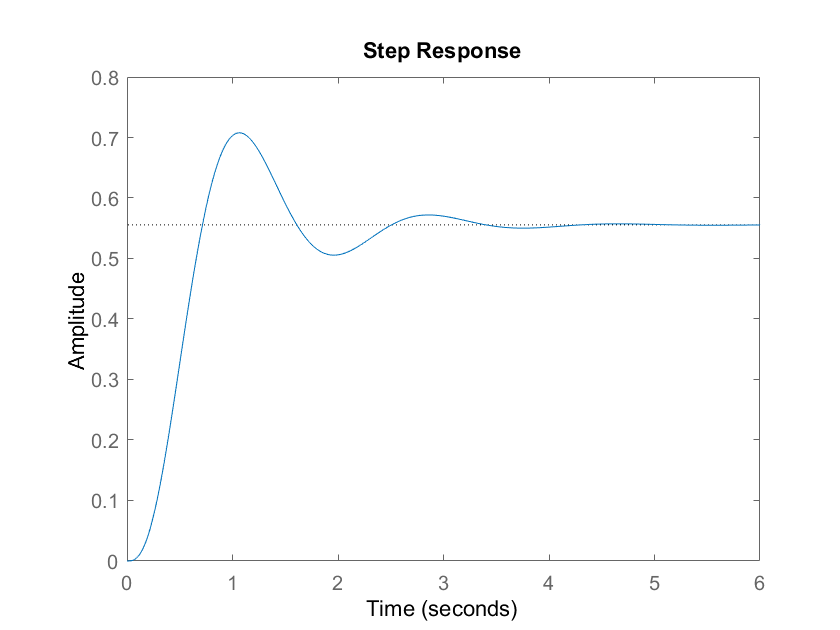

clf(f1)
f2 = figure;
step(feedback(K*G,1));

clf(f2)
st = ["unstable","stable"];
disp("The closed-loop system is "+ st(isstable(feedback(K*G,1))+1))

The closed-loop system is stable


From your investigation you should observe that when $K=1$the gain has no effect on the original open-loop Bode plot. Increasing $K$then shifts the magnitude plot up which eats away at the system's gain margin until the gain margin becomes negative, indicating the closed-loop system is unstable with that value of $K$. (A value of $K$ less than 1 and greater than 0 causes the magnitude plot to shift down because the additional gain in decibels is negative.) The additional loop gain does not affect the phase plot, but shifting the magnitude plot upward does increase the gain crossover frequency which reduces the phase margin for this system because the system has more phase lag at higher frequencies.

**Bandwidth Frequency**

The bandwidth frequency is defined as the frequency at which the closed-loop magnitude drops 3 dB below its magnitude at DC (magnitude as the frequency approaches 0). However, when we design via frequency response, we are interested in predicting the closed-loop behavior from the open-loop response. Therefore, we will use a second-order system approximation and say that the bandwidth frequency equals the frequency at which the open-loop magnitude response is between -6 and -7.5 dB, assuming the open-loop phase response is between -135 deg and -225 deg. For a complete derivation of this approximation, consult your textbook.

In order to illustrate the importance of the bandwidth frequency, we will show how the output changes with different input frequencies. We will find that sinusoidal inputs with frequency less than $\omega_{bw}$ (the bandwidth frequency) are tracked "reasonably well" by the system. Sinusoidal inputs with frequency greater than $\omega_{bw}$ are attenuated (in magnitude) by a factor of 0.707 or greater (and are also shifted in phase).

Let's say we have the following closed-loop transfer function representing a system:


$$
G(s) = \frac{1}{s^2 + 0.5s + 1}
$$


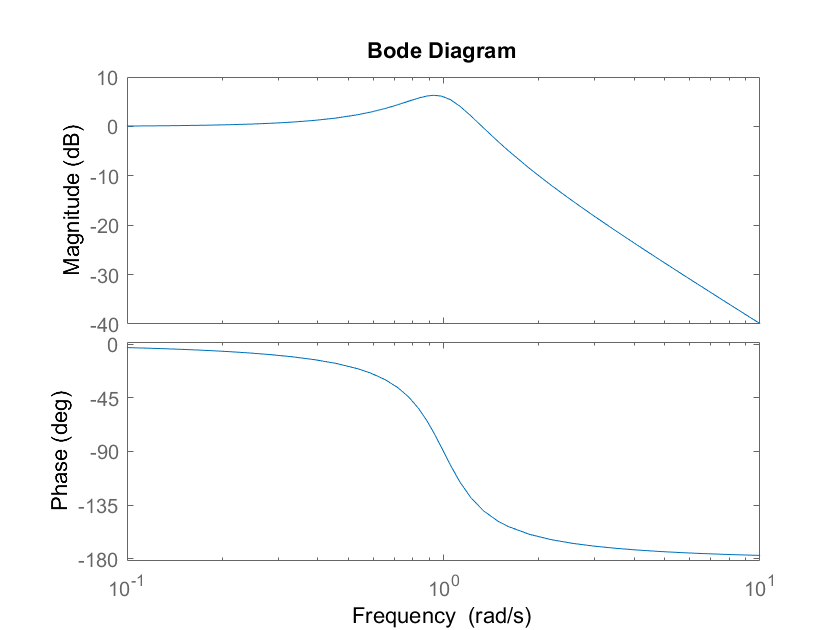

G = 1/(s^2 + 0.5*s + 1);
bode(G)

Since this is the closed-loop transfer function, our bandwidth frequency will be the frequency corresponding to a gain of -3 dB. Looking at the plot, we find that it is approximately 1.4 rad/s. We can also read off the plot that for an input frequency of 0.3 radians, the output sinusoid should have a magnitude about one and the phase should be shifted by perhaps a few degrees (behind the input). For an input frequency of 3 rad/sec, the output magnitude should be about -20 dB (or 1/10 as large as the input) and the phase should be nearly -180 (almost exactly out-of-phase). 

The following livescript employs the `lsim` command to simulate the response of the system to sinusoidal inputs of different frequencies. The black box on the Bode plot corresponds to the chosen frequency and indicates how the steady-state output should be scaled and shifted for a sinusoidal input of that frequency. Keep in mind that we want to view the steady-state response. Therefore, we modify the axes for the plot of sinusoidal output in order to see the steady-state response clearly (ignoring the transient response). First, consider sinusoidal inputs with **frequencies lower than **$\omega_{bw} \approx 1.4$ rad/sec. Then set the frequency of the input **higher than the bandwidth frequency** for the system. Observe how the system's response changes for these two regions.

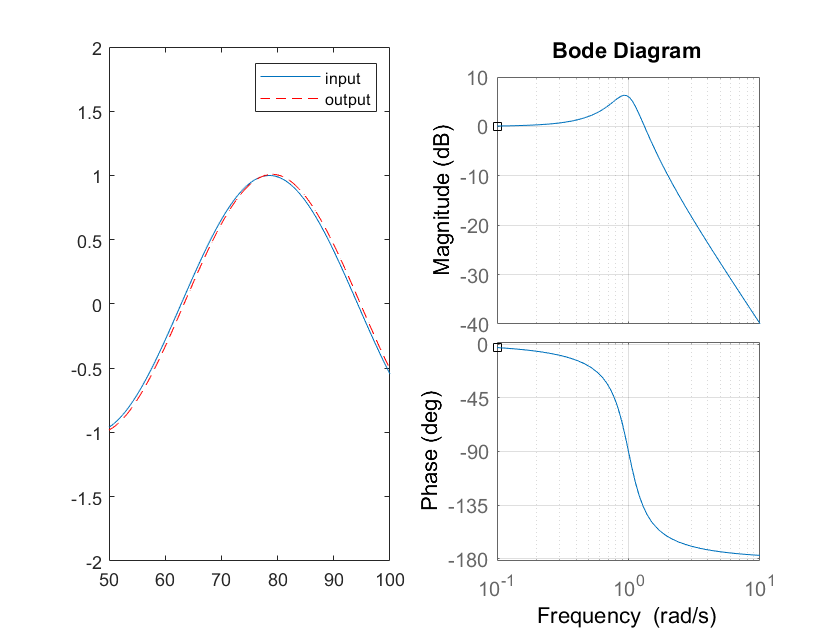

G = 1/(s^2 + 0.5*s + 1);
w =0.1;
t = 0:0.1:100;
u = sin(w*t);
[y,t] = lsim(G,u,t);
f3 = figure;
subplot(1,2,1)
subplot(1,2,2)
bode(G,w,'ks')
grid
hold on;
bode(G,{0.1,10});
subplot(1,2,1)
plot(t,u,t,y,'r--')
legend('input','output')
axis([50 100 -2 2])

clf(f3)

What you should have observed is that for inputs with frequency below the bandwidth frequency, the output (red) tracks the input (blue) fairly well; the steady-state output is perhaps a few degrees behind the input and slightly amplified, but that is expected. However, if we set the frequency of the input higher than the bandwidth frequency for the system, we get a very distorted response (with respect to the input). Specifcally, the steady-state output becomes increasingly attenuated and almost exactly out of phase (180 degrees behind) the input. 

## Nyquist Diagram

The Nyquist diagram allows us to predict the stability and performance of a closed-loop system by observing its open-loop behavior. The Nyquist criterion can be used for design purposes regardless of open-loop stability (remember that the Bode design methods assume that the system is stable in open-loop). Therefore, we use this criterion to determine closed-loop stability when the Bode plots display confusing information. 

**Note: The MATLAB** `nyquist`** command does not provide an adequate representation for systems that have open-loop poles on the imaginary axis.** Therefore, we suggest that you copy the [nyquist1.m](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_nyquist1) file as a new  `m-file`. This `m-file` creates more accurate Nyquist plots, since it correctly deals with poles and zeros on the imaginary axis.

The Nyquist diagram is basically a plot of $G(j\omega)$ where $G(s)$ is the open-loop transfer function and $\omega$ is a vector of frequencies which encloses the entire right-half plane. In drawing the Nyquist diagram, both positive (from zero to infinity) and negative frequencies (from negative infinity to zero) are taken into account. We will represent positive frequencies in red and negative frequencies in green. The frequency vector used in plotting the Nyquist diagram usually looks like this (if you can imagine the plot stretching out to infinity):

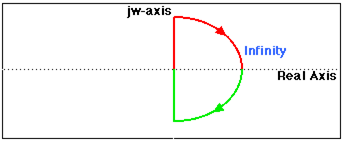

However, if we have open-loop poles or zeros on the imaginary axis, $G(s)$ will not be defined at those points and we must loop around them when we are plotting the contour. An example contour would appear as follows:

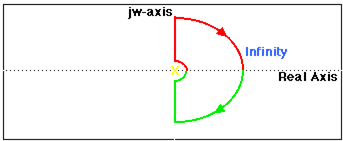

Please note that the contour loops around the pole on the imaginary axis. As we mentioned before, the MATLAB `nyquist` command does not take poles or zeros on the imaginary axis into account and, therefore, produces an incorrect plot. To correct this, please download and use [nyquist1.m](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_nyquist1). If we have a pole on the imaginary axis, we have to use `nyquist1`. If there are no poles or zeros on the imaginary axis, or if we have pole-zero cancellation, we can use either the `nyquist` command or `nyquist1.m`.

## The Cauchy Criterion

The Cauchy criterion (from complex analysis) states that when taking a closed contour in the complex plane, and mapping it through a complex function $G(s)$, the number of times that the plot of $G(s)$ encircles the origin is equal to the number of zeros of $G(s)$ enclosed by the frequency contour minus the number of poles of $G(s)$ enclosed by the frequency contour. Encirclements of the origin are counted as positive if they are in the same direction as the original closed contour or negative if they are in the opposite direction.

When studying feedback control, we are not as interested in $G(s)$ and, rather, are more concerned with the closed-loop transfer function:


$$
\frac{G(s)}{1 + G(s)}
$$


If $1 + G(s)$ encircles the origin, then $G(s)$ will enclose the point -1. Since we are interested in the closed-loop stability, we want to know if there are any closed-loop poles (zeros of $1 + G(s)$) in the right-half plane. More details on how to determine this will come later.

Therefore, the behavior of the Nyquist diagram around the -1 point in the real axis is very important; however, the axis on the standard `nyquist` diagram might make it hard to see what's happening around this point. To correct this, you can add the [lnyquist.m](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_lnyquist) function to your files. The  `lnyquist.m` command plots the Nyquist diagram using a logarithmic scale and preserves the characteristics of the -1 point.

To view a simple Nyquist plot using MATLAB, we will define the following transfer function and view the Nyquist plot:


$$
G(s) = \frac{0.5}{s - 0.5}
$$


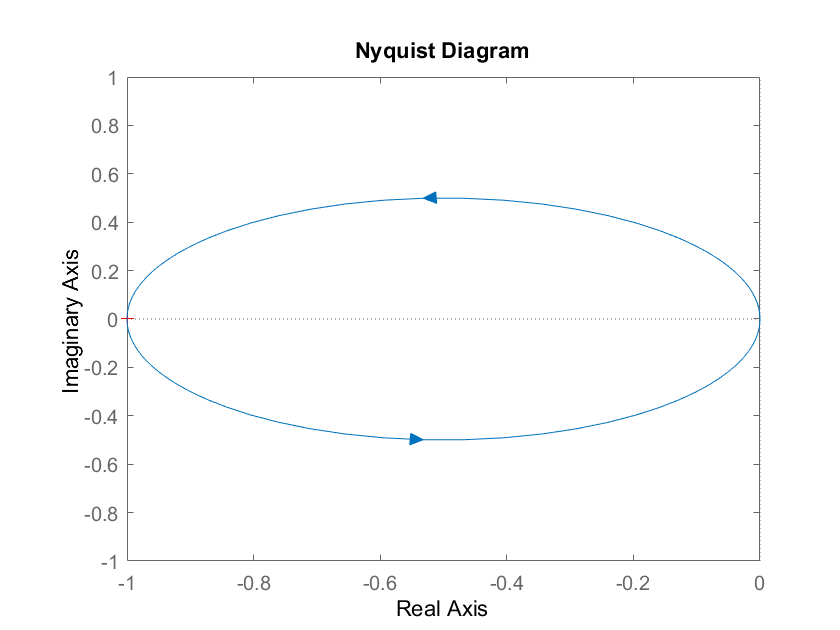

s = tf('s');
G = 0.5/(s - 0.5);
nyquist(G)
axis([-1 0 -1 1])

Now we will look at the Nyquist diagram for the following transfer function:


$$
G(s) = \frac{s + 2}{s^2}
$$


Note that this function has a pole at the origin. We will see the difference between using the `nyquist`, `nyquist1`, and `lnyquist` commands with this particular function.

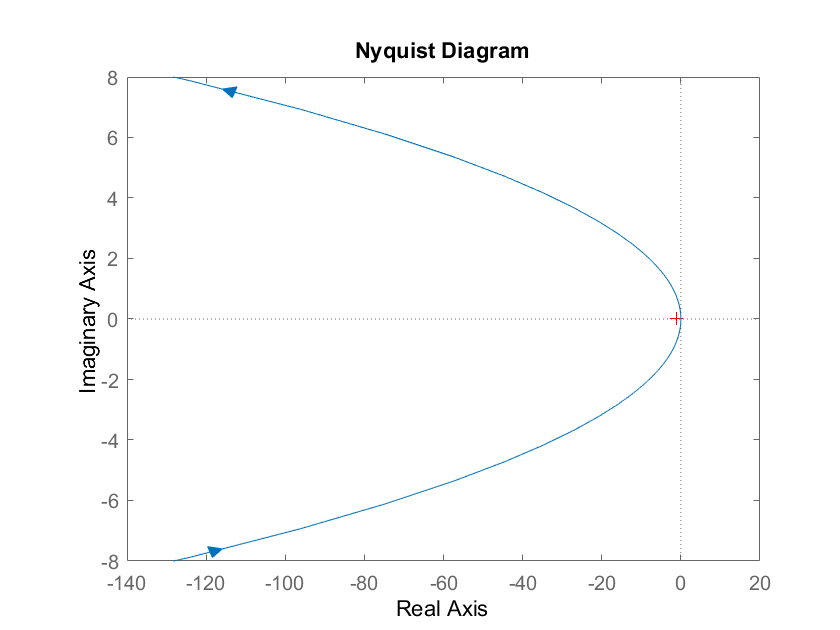

G = (s + 2)/(s^2);
nyquist(G)

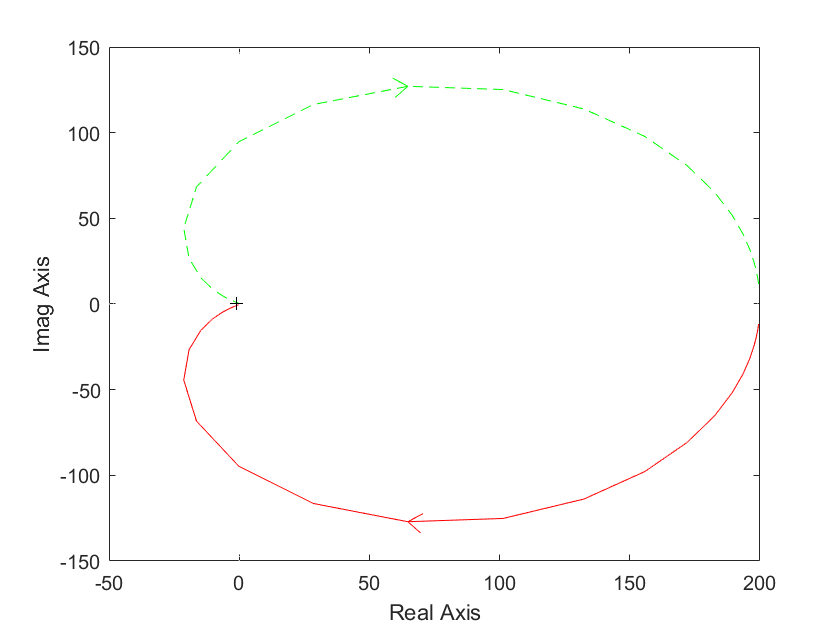

nyquist1(G)

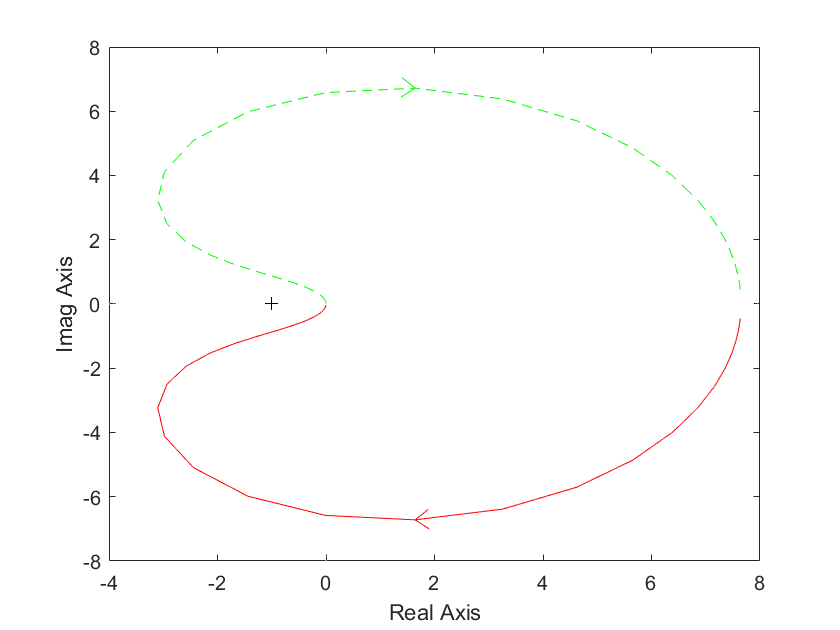

lnyquist(G)

Note that the `nyquist` plot is not correct. In particular, it does not capture the behavior of the Nyquist plot for a radius approaching infinity ($s$ approaching 0). The `nyquist1` plot has the correct shape, which allows us to evaluate encirclements of the -1 point and apply the Nyquist criterion, but it's difficult to see what happens close to the -1 point. The `lnyquist` function employs a modified scale that maintains the correct behavior of the plot near the -1 point and keeps the correct basic shape.

## Closed-Loop Performance from Bode Plots

As discussed so far in this page, closed-loop stability can be assessed based on a system's open-loop frequency response. Design of closed-loop control also is generally performed using open-loop frequency response. In order to predict closed-loop performance based on open-loop frequency response, we need to make a few assumptions:

- The system must be stable in open-loop if we are going to use Bode plots for our design.

- For canonical second-order systems, the closed-loop damping ratio is approximately equal to the phase margin divided by 100 if the phase margin is between 0 and 60 degrees. We can use this concept with caution if the phase margin is greater than 60 degrees.

- For canonical second-order systems, a relationship between damping ratio, bandwidth frequency, and settling time is given by an equation described on the [Extras: Bandwidth](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_wbw) page.

- A very rough estimate that you can use, is that the bandwidth is approximately equal to the natural frequency.

Let's use these concepts to design a controller for the following system:

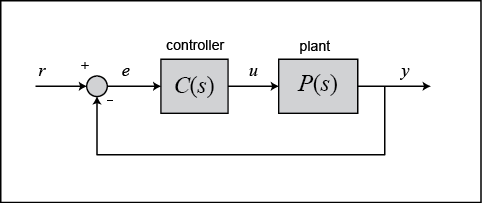

Where $C(s)$ is the controller and $P(s)$ is:


$$
P(s) = \frac{10}{1.25s + 1}
$$


The design must meet the following specifications:

- Zero steady-state error

- Maximum overshoot must be less than 40%

- Settling time must be less than 2 seconds

There are two ways of solving this problem: one is graphical and the other is numerical. Within MATLAB, the graphical approach is best, so that is the approach we will use. First, let's look at the Bode plot. Create an `m-file` with the following code:

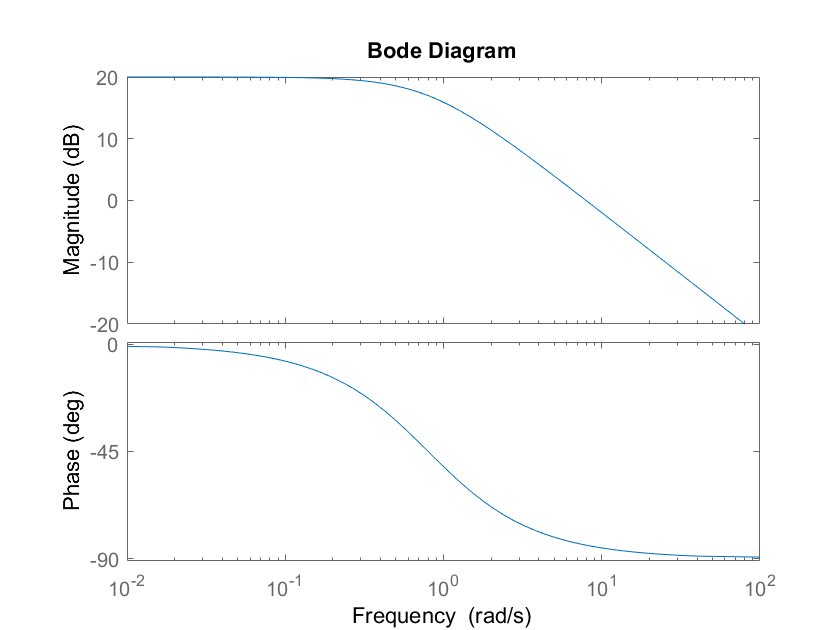

P = 10/(1.25*s + 1);
bode(P)

There are several characteristics of the system that can be read directly from this Bode plot. First of all, we can see that the bandwidth frequency is around 10 rad/sec. Since the bandwidth frequency is roughly the same as the natural frequency (for a first-order system of this type), the rise time is 1.8/BW = 1.8/10 = 0.18 seconds. This is a rough estimate, so we will say the rise time is about 0.2 seconds.

The phase margin for this system is approximately 95 degrees. The relation, damping ratio = PM/100, only holds for PM < 60. Since the system is first-order, there should be no overshoot.

The last major point of interest is **steady-state error**. The steady-state error can be read directly off the Bode plot as well. The error constant ($K_p$, $K_v$, or $K_a$) is found from the intersection of the low frequency asymptote with the $\omega$ = 1 rad/sec line. Just extend the low frequency line to the $\omega$ = 1 line. The magnitude at this point is the error constant. Since the Bode plot of this system is a horizontal line at low frequencies (slope = 0), we know this system in unity feedback is type zero. Therefore, the intersection is easy to find. The gain is 20 dB (magnitude 10), meaning that the constant for the error function is 10. The steady-state error is thus 1/(1+ $K_p$) = 1/(1+10) = 0.091. 

If our system was type one instead of type zero, the constant for the steady-state error would be found in a manner similar to the following.

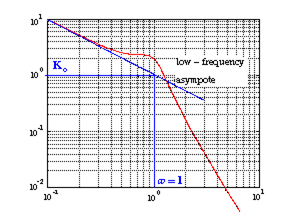

Let's check our predictions by looking at a step response plot. This can be done by executing the following lines of code.

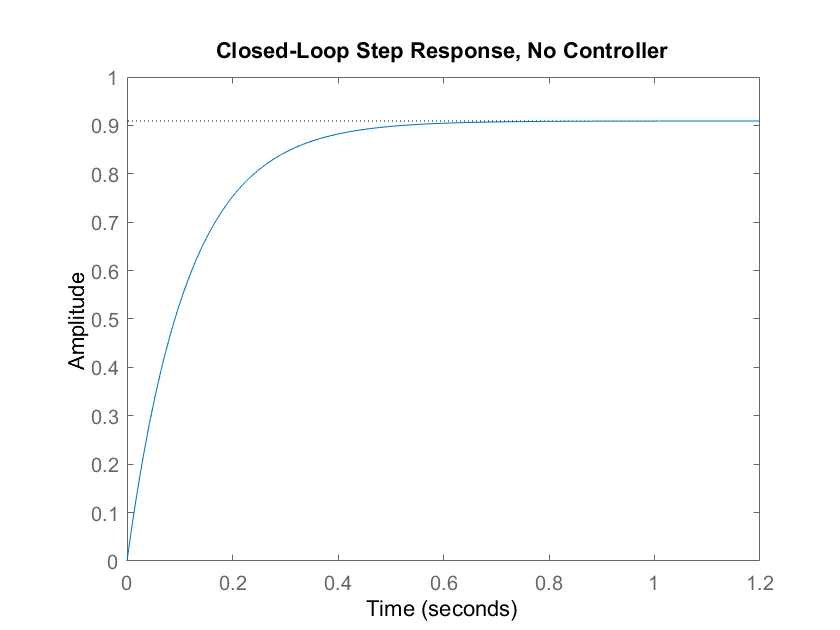

sys_cl = feedback(P,1);
step(sys_cl)
title('Closed-Loop Step Response, No Controller')

As you can see, our predictions were very good. The system has a rise time of about 0.2 seconds, has no overshoot, and has a steady-state error of about 9%. Now we need to choose a controller that will allow us to meet the design criteria. We choose a PI controller because it will yield zero steady-state error for a step input. Also, the PI controller has a zero, which we can place. This gives us additional design flexibility to help us meet our criteria. Recall that a PI controller has the following form:


$$
C(s) = \frac{K(\frac{1}{T}s + 1)}{s} = \frac{K}{T} + \frac{K}{s}
$$


The first thing we need to find is the damping ratio corresponding to a percent overshoot of 40%. Plugging this value into the equation relating overshoot and damping ratio (or consulting a plot of this relation), we find that the damping ratio corresponding to this overshoot is approximately 0.28. Therefore, our phase margin should be at least 30 degrees. Furthermore, we must have a bandwidth frequency greater than or equal to 12 rad/sec if we want our settling time to be less than 1.75 seconds which meets the design specifications.

Now that we know our desired phase margin and bandwidth frequency, we can start our design. Remember that we will conduct our design using the open-loop Bode plots. Therefore, our bandwidth frequency will be the frequency corresponding to a gain of approximately -7 dB. By examination of the form of the PI controller, we have two degrees of freedom we can adjust, the loop gain $K$ and the location of the zero $T$ (alternatively $K_p =\frac{K}{T}$ and $K_i =K$). In the following interactive live script, there are sliders for each of these two parameters. We will experiment with each parameter separately and observe the effect on the resulting open-loop Bode plot and closed-loop step response. For example, let the zero be placed at $T=5$ and then adjust the loop gain $K$and observe the change in behavior. 

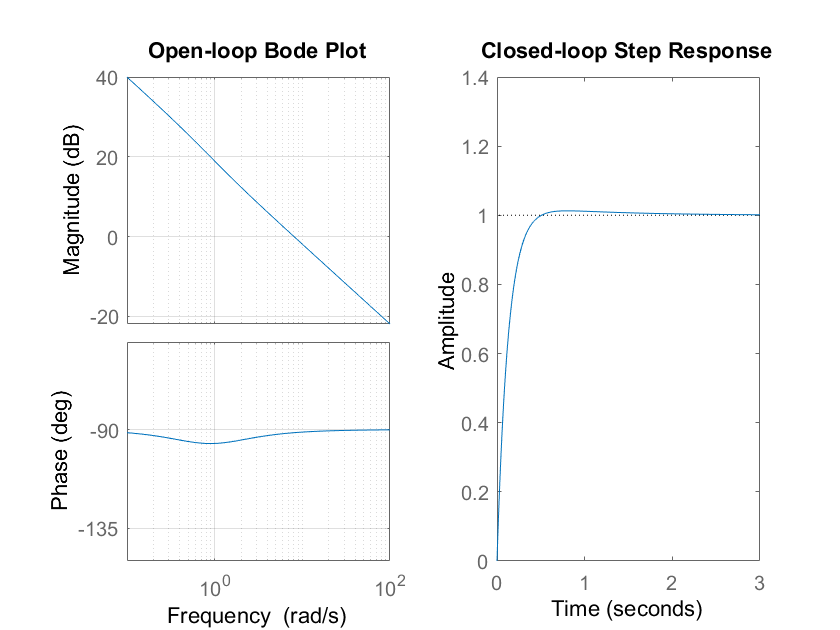

s = tf('s');
P = 10/(1.25*s + 1);
K =1;
T = 1;
C = K*(s/T+1)/s;
f4 = figure;
subplot(1,2,2)
subplot(1,2,1)
bode(C*P, logspace(-1,2));
axis([0.1 100 -150 -50])
title('Open-loop Bode Plot')
grid
subplot(1,2,2)
sys_cl = feedback(C*P,1);
step(sys_cl);
axis([0 3 0 1.4])
title('Closed-loop Step Response')

clf(f4);

For this set zero location, changing the loop gain $K$won't affect the phase plot, but it will move the magnitude plot up for values greater than 1, and down for values less than 1. With $K=1$, the gain crossover frequency occurs at approximately 3 rad/sec resulting in a phase margin of approximately 45 degrees. Reducing the value of $K$shifts the magnitude plot down causing the gain crossover frequency (and bandwidth frequency) to move left to a point where the phase is larger. The smaller bandwidth frequency is indicated by a slower step response, while the larger phase margin corresponds to a reduction in maximum percent overshoot. Increasing the value of the gain $K$shifts the magnitude plot up causing the gain crossover frequency (and bandwidth frequency) to move move in the opposite direction to the right, to a point where the phase is also larger. The larger bandwith frequency results in a faster step response, while the larger phase margin again results in a reduction in overshoot. Since this is a type one system, the steady-state error for a step input will always be zero. Increasing the loop gain does correspond to a larger value of $K_i$ and a larger velocity error constant. This means that for a step the error will go to zero more quickly, and for a ramp input, the steady-state error would be reduced. 

Now let the loop gain be constant, for example $K=5$, and observe the effect of adjusting the location of the zero. Changing the location of the zero changes the frequency of the zero's break. Recall that a zero adds a postive 20 dB/decade of slope to the magnitude plot after its break frequency, while adding a positive 90 degrees of phase.

## Closed-Loop Stability from the Nyquist Diagram

Consider the negative feedback system:

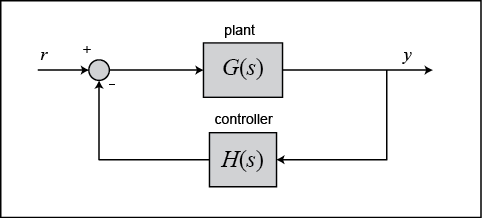

Remember from the Cauchy criterion that the number (`N`) of times that the plot of $G(s)H(s)$ encircles **-1+j.0** is equal to the number (`Z`) of zeros of  $1 + G(s)H(s)$ enclosed by the frequency contour minus the number (`P`) of poles of $1 + G(s)H(s)$ enclosed by the frequency contour `(N = Z - P)`. Keeping careful track of the open- and closed-loop transfer functions, as well as numerators and denominators, you should convince yourself that: 

- The zeros of $1 + G(s)H(s)$ are the poles of the closed-loop transfer function.

- The poles of $1 + G(s)H(s)$ are the poles of the open-loop transfer function.

Based on the above definitions:

- `P` = the number of open-loop (unstable) poles of $G(s)H(s)$.

- `N` = the number of times the Nyquist diagram encircles -1.

- clockwise encirclements of -1 count as positive encirclements.

- counter-clockwise encirclements of -1 count as negative encirclements.

- `Z` = the number of right-half-plane (positive, real) poles of the closed-loop system.

The Nyquist Stability Criterion that relates these three quantities is then:


$$
Z = P + N
$$


**Note: This is only one convention for the Nyquist criterion. Another convention states that a positive** `N`** counts the counterclockwise or anti-clockwise encirclements of -1. The** `P`** and** `Z`** variables remain the same. In this case the equation becomes** `Z = P - N`**. Throughout these tutorials, we will use a positive sign for clockwise encirclements.**

It is very important (and somewhat tricky) to learn how to count the number of times that the Nyquist diagram encircles -1. Therefore, we will go into some detail to help you visualize this. One approach is to imagine you are standing on top of the -1 point and are following the diagram from beginning to end. Now ask yourself: How many times did I turn my head a full 360 degrees? Again, if the motion was clockwise, `N` is positive, and if the motion is counterclockwise, `N` is negative.

Knowing the number of right-half plane (unstable) poles of the open loop (`P`), and the number of encirclements of -1 made by the Nyquist diagram (`N`), we can determine the closed-loop stability of the system. If  `Z = P + N` is a positive, nonzero number, the closed-loop system is unstable.

We can also use the Nyquist diagram to find the range of gains for a closed-loop unity feedback system to be stable. The system we will test looks like this:

where:


$$
G(s) = \frac{s^2 + 10s + 24}{s^2 - 8s + 15}
$$


This system has a gain $K$ which can be varied in order to modify the response of the closed-loop system. However, we will see that we can only vary this gain within certain limits, since we have to make sure that our closed-loop system will be stable. This is what we will be looking for: the range of gains that will make this system stable in the closed-loop.

The first thing we need to do is find the number of positive real poles in our open-loop transfer function:

roots([1 -8 15])

ans =      5
     3


The poles of the open-loop transfer function are both positive. Therefore, we need two counterclockwise (`N = -2`) encirclements of the Nyquist diagram in order to have a stable closed-loop system (`Z = P + N`). If the number of encirclements is less than two or the encirclements are not counterclockwise, our system will be unstable.

Let's look at our Nyquist diagram for a gain of 1:

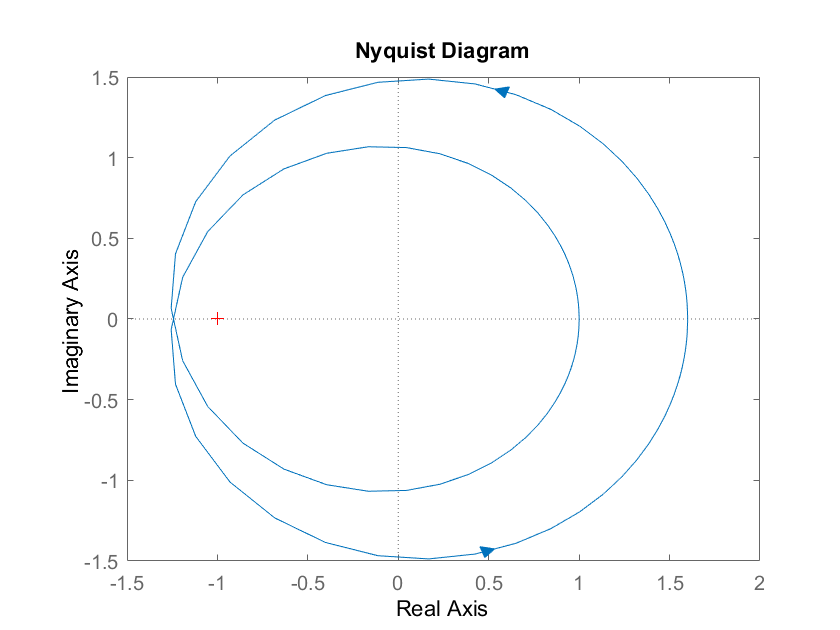

G = (s^2 + 10*s + 24)/(s^2 - 8*s + 15);
nyquist(G)

There are two counterclockwise encirclements of -1. Therefore, the system is stable for a gain of 1. 

Now observe how the system behaves if we adjust the gain. In the following interactive live script, use the slider to adjust the loop gain $K$being added to the system. Recall, adding a loop gain adjusts the open-loop system's magnitude, but not its phase. Therefore, we can imagine that as the gain $K$ is adjusted, every point on Nyquist plot has the same phase angle, but its distance from the origin changes in accordance with whether $K$ is increasing or decreasing.

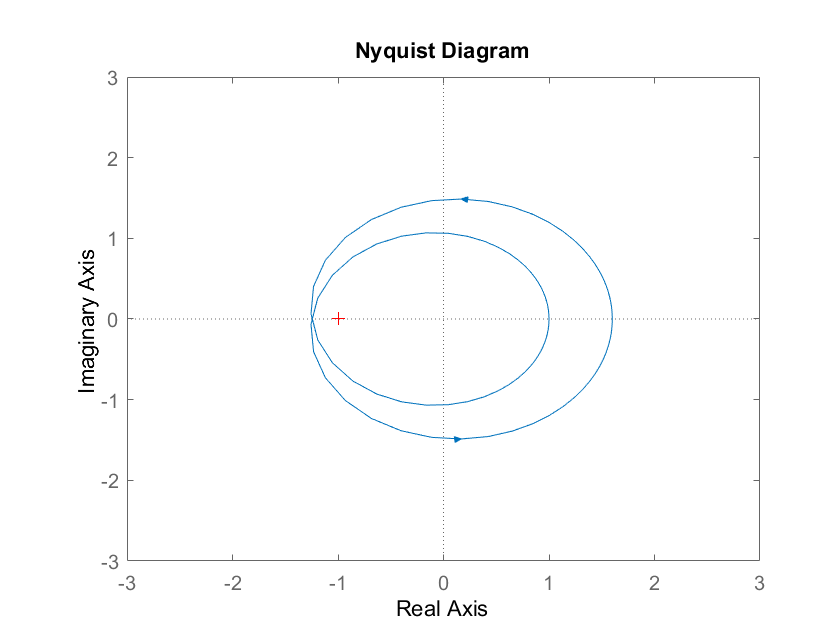

G = (s^2 + 10*s + 24)/(s^2 - 8*s + 15);
K = 1;
nyquist(K*G);
axis([-3 3 -3 3])

You should have observed that as $K$was increased, the diagram expanded. Since the encirclements of -1 remained the same, the closed-loop system remains stable as $K$is increased to values greater than one. However, you should have also observed that reducing $K$caused the diagram to contract. If you decrease the gain enough, the Nyquist plot no longer encircles the -1 point and the system becomes unstable. This transition appears to occur for a loop gain value of approximately 0.8.

**Gain Margin**

We already defined the gain margin as the change in open-loop gain expressed in decibels (dB), required at -180 degrees of phase shift to make the open-loop magnitude equal 0 dB. In the previous section, our interactive live script demonstrated a situation where the gain could be increased infinitely, but the closed-loop system became unstable for $K$less than approximately 0.8. We will investigate the concept of gain margin in some more depth here. First of all, let's say that we have a system that is stable if there are no Nyquist encirclements of -1, such as:


$$
G(s) = \frac{50}{s^3 + 9s^2 + 30s + 40}
$$


Looking at the roots, we find that we have no open loop poles in the right-half plane. Therefore, there are no closed-loop poles in the right-half plane if there are no Nyquist encirclements of -1. Now, how much can we vary the gain before this system becomes unstable in closed-loop? Let's look at the following figure:

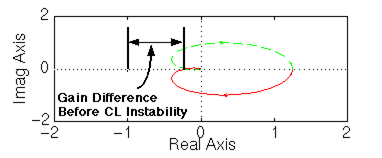

The open-loop system represented by this plot will become unstable in closed loop if the gain is increased past a certain boundary. The negative real axis area between `-1/a` (defined as the point where the open-loop has -180 degree of phase, that is, where the diagram crosses the real axis) and -1 represents the amount of increase in gain that can be tolerated before closed-loop instability.

If we think about it, we realize that if the added gain is equal to `a`, the diagram will touch the -1 point: 


$$
G(j\omega) = \frac{-1}{a}
$$


or


$$
aG(j\omega) = -1
$$


Therefore, we say that the gain margin is `a` units. However, we mentioned before that the gain margin is usually measured in decibels. Hence, the gain margin is:


$$
GM = 20\log_{10}(a)\ \mathrm{dB}
$$


We will now find the gain margin of the stable, open-loop transfer function we viewed before. Recall that the function is:


$$
G(s) = \frac{50}{s^3 + 9s^2 + 30s + 40}
$$


and that the Nyquist diagram can be viewed by typing:

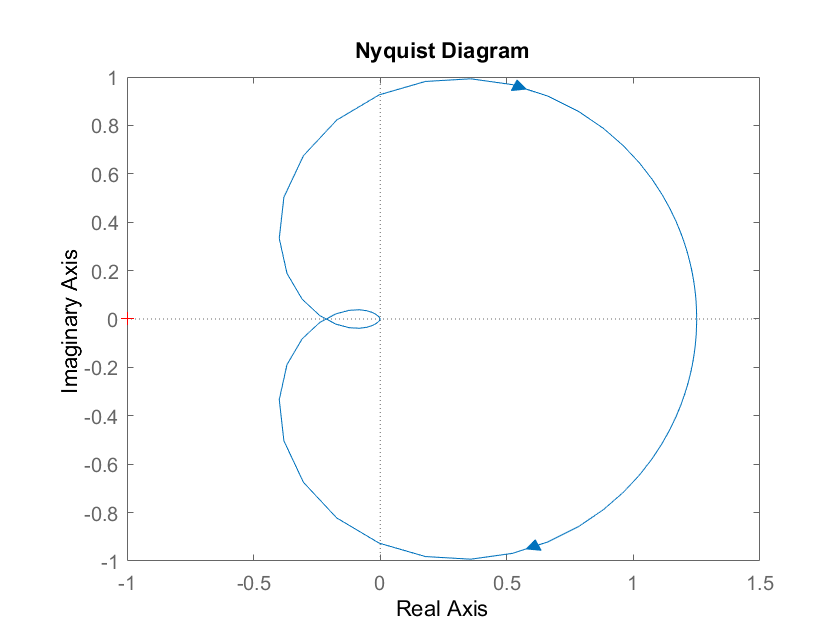

G = 50/(s^3 + 9*s^2 + 30*s + 40);
nyquist(G)

As we discussed before, all that we need to do to find the gain margin is find `a`, as defined in the preceding figure. To do this, we need to find the point where there is exactly -180 degrees of phase shift. This means that the transfer function at this point is real (has no imaginary part). The numerator is already real, so we just need to look at the denominator. When $s = j\omega$, the only terms in the denominator that will have imaginary parts are those which are odd powers of `s`. Therefore, for $G(jw)$ to be real, we must have:


$$
-j\omega^3 + 30j\omega = 0
$$


which means $\omega = 0$ (this is the rightmost point in the Nyquist diagram) or $\omega = \sqrt{30}$. We can then find the value of $G(j\omega)$ at this point using `polyval`:

w = sqrt(30);
polyval(50,1j*w)/polyval([1 9 30 40],1j*w)

ans = -0.2174

The answer is: `-0.2174 + 0i`. The imaginary part is zero, so we know that our answer is correct. We can also verify this by looking at the Nyquist plot again. The real part also makes sense. Now we can proceed to find the gain margin.

We found that the -180 degrees phase shift occurs at `-0.2174 + 0i`. This point was previously defined as `-1/a`. Therefore, we now have `a`, which is the gain margin. However, we need to express the gain margin in decibels:


$$ \frac{-1}{a} = -0.2174 $$



$$ \Rightarrow a = 4.6 $$



$$ \Rightarrow GM = 20\log_{10}(4.6) = 13.26\ \mathrm{dB} $$


We now have our gain margin. Let's see how accurate it is by using a gain of `a = 4.6` and zooming in on the Nyquist plot:

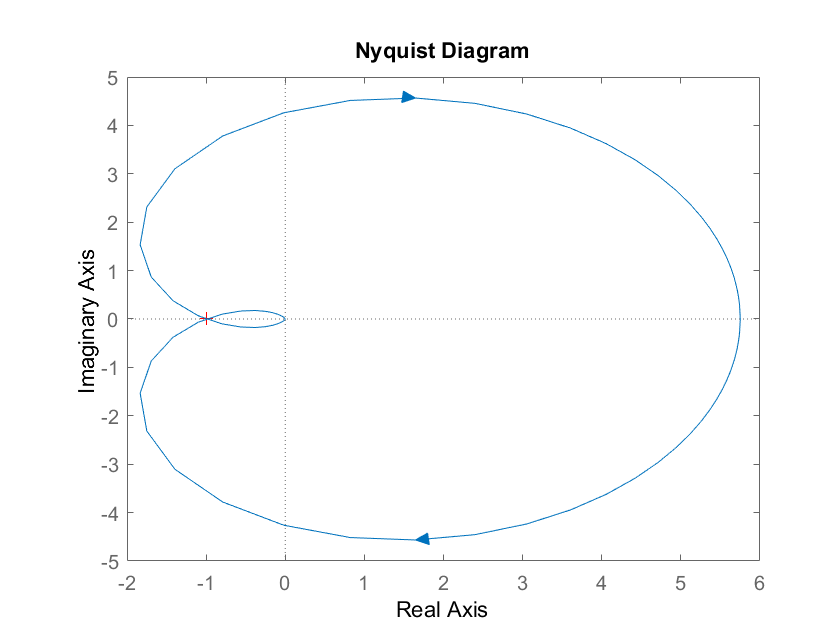

a = 4.6;
nyquist(a*G)

In the following interactive live script, you can adjust the value of the gain `a` and observe the effect on the Nyquist diagram of the open-loop system, as well as the closed-loop step response.

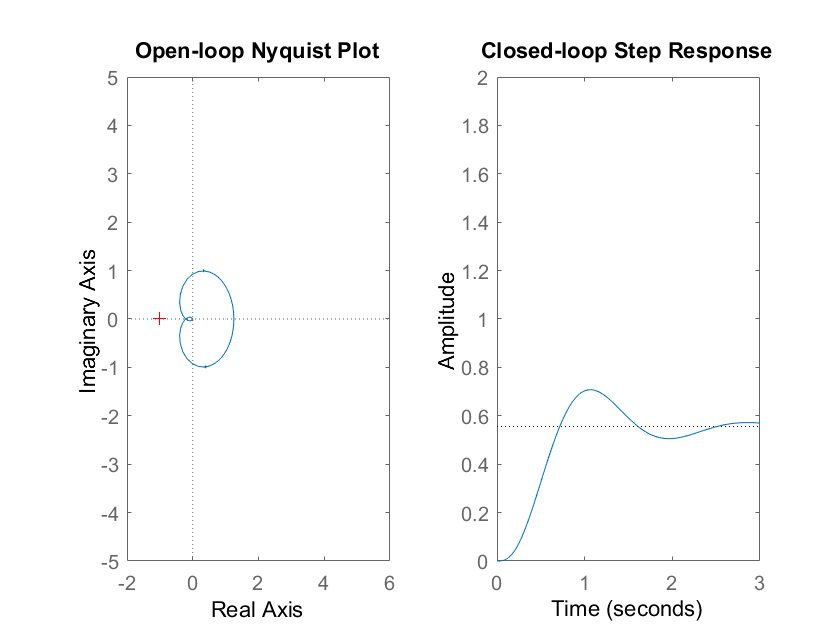

a =1;
G = 50/(s^3 + 9*s^2 + 30*s + 40);
f5 = figure;
subplot(1,2,2)
subplot(1,2,1)
nyquist(a*G);
axis([-2 6 -5 5])
title('Open-loop Nyquist Plot')
subplot(1,2,2)
step(feedback(a*G,1),[0:0.01:3]);
axis([0 3 0 2])
title('Closed-loop Step Response')

clf(f5)

**Phase Margin**

We have already discussed the importance of the phase margin. Therefore, we will only talk about where this concept comes from. We have defined the phase margin as the change in open-loop phase shift required at unity gain to make a closed-loop system unstable. Let's look at the following graphical definition of this concept to get a better idea of what we are talking about. 

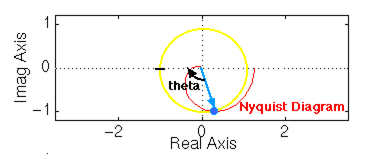

Let's analyze the previous plot and think about what is happening. From our previous example we know that this particular system will be unstable in closed-loop if the Nyquist diagram encircles the -1 point. However, we must also realize that if the diagram is shifted by `theta` degrees, it will then touch the -1 point at the negative real axis, making the system marginally stable in closed-loop. Therefore, the angle required to make this system marginally stable in closed-loop is called the phase margin (measured in degrees). In order to find the point we measure this angle from, we draw a circle with radius of 1, find the point in the Nyquist diagram with a magnitude of 1 (gain of 0 dB), and measure the phase shift needed for this point to be at an angle of -180 degrees. In our previous system, the circle of radius 1 crosses the Nyquist plot at approximately 101 degrees which corresponds to the system's phase margin. In the following, the slider allows you to adjust the phase shift added to the system. Looking at the Nyquist diagram, you can imagine that the angle of each point with frequency 0 to $\infty$ has the amount of phase indicated by the slider added to it. (The points with frequency -$\infty$ to 0 are just the reflection.) In some sense, you can imagine the Nyquist diagram is being folded. Experimenting with the slider, you should observe that adding approximately -101 degrees of phase shift causes an encirclement of the -1 point. 

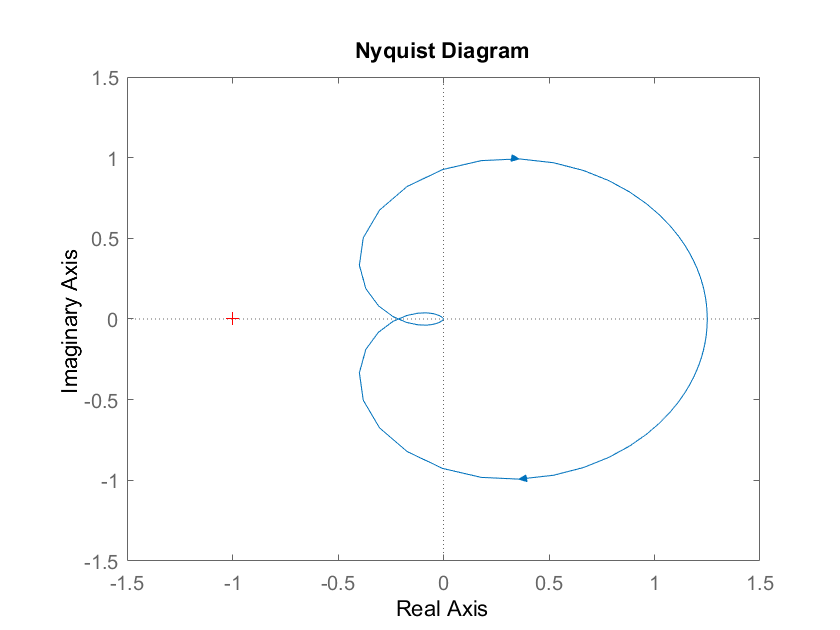

phase =0;
G = 50/(s^3 + 9*s^2 + 30*s + 40);
shift = cosd(phase) + sind(phase)*1i;
f6 = figure;
nyquist(shift*G)
axis([-1.5 1.5 -1.5 1.5])

clf(f6)

**Disk Margin**

A limitation of traditional gain and phase margin is that it assesses a system's robustness based on only two frequencies and it treats gain and phase margin in isolation. One could imagine a situation where a system has a robust gain margin at the phase crossover frequency, but that the gain margin could become positive with just a slight shift in phase. A concept that can give a more complete picture of stability is the **disk margin**. With the nominal disk margin, you can imagine a disk centered at the -1 point that is just tangent to the Nyquist plot without crossing the plot. The larger the disk, the more stability margin the system has. The following interactive live script demonstrates the disk margin for our system employing the `diskmargin` and `diskmarginplot `commands.  The slider control allows you to adjust the skew of your disk where negative values allow more gain decrease than increase, postive values allow more gain increase than decrease, and a skew of zero indicates the increase and decrease are balanced.

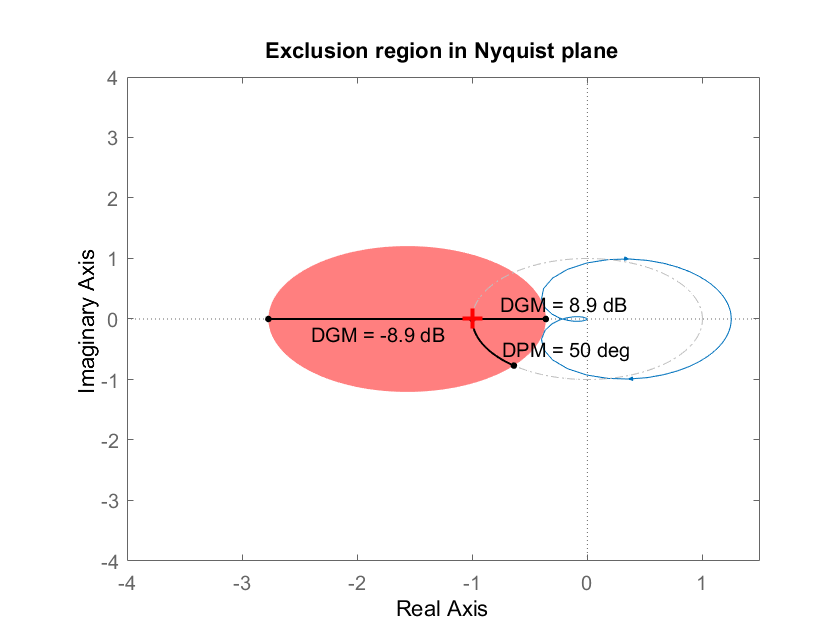

G = 50/(s^3 + 9*s^2 + 30*s + 40);
skew =0;
DM = diskmargin(G,skew);
DGM = DM.GainMargin;
f7 = figure;
nyquist(G)
hold on
diskmarginplot(DGM,'nyquist')
axis([-4 1.5 -4 4])
hold off

clf(f7)